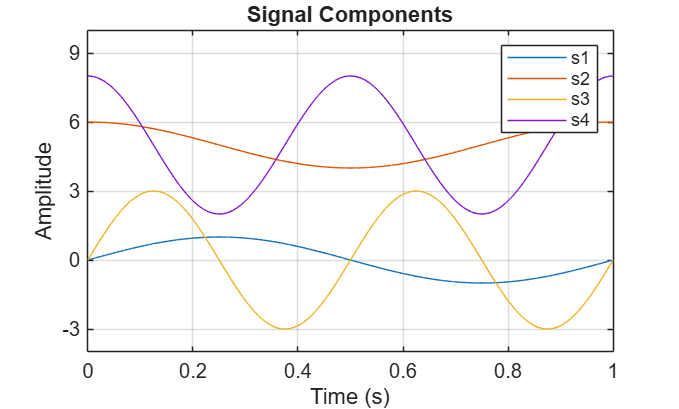

clear
clc

tn = linspace(0, 1, 5001);

s1 = sin(2*pi*tn);
s2 = sin(2*pi*tn + pi/2) + 5;
s3 = 3*sin(2*pi*2*tn);
s4 = 3*sin(2*pi*2*tn + pi/2) + 5;

figure;
S = [s1(:) s2(:) s3(:) s4(:)];
plot(tn, S);
grid on;
title('Signal Components');
legend('s1', 's2', 's3', 's4');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-4, 10]);
yticks(-3:3:9);


mean_s1 = mean(s1)

mean_s1 = 3.1992e-17

mean_s2 = mean(s2)

mean_s2 = 5.0002

mean_s3 = mean(s3)

mean_s3 = 7.4456e-17

mean_s4 = mean(s4)

mean_s4 = 5.0006


var_s1 = var(s1,1)

var_s1 = 0.4999

var_s2 = var(s2, 1)

var_s2 = 0.5001

var_s3 = var(s3, 1)

var_s3 = 4.4991

var_s4 = var(s4, 1)

var_s4 = 4.5009


power_s1 = mean(s1.^2)

power_s1 = 0.4999

power_s2 = mean(s2.^2)

power_s2 = 25.5021

power_s3 = mean(s3.^2)

power_s3 = 4.4991

power_s4 = mean(s4.^2)

power_s4 = 29.5069

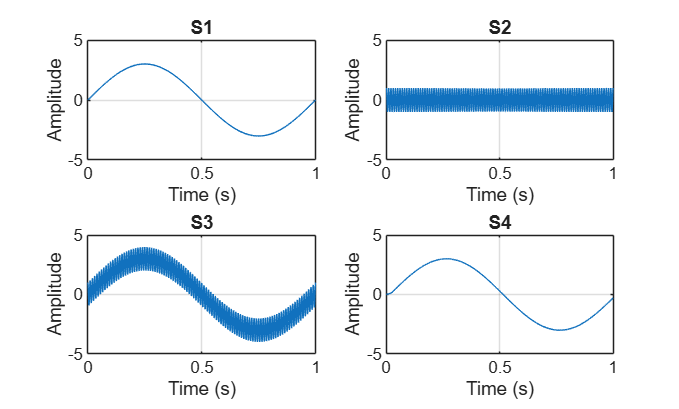


tn = linspace(0,1,1000);
s1 = 3*sin(2*pi*tn);
s2 = sin(200*pi*tn + pi/2);
s3 = s1 + s2;
b = fir1(30, 3.1479e-4); 
s4 = filter(b,1,s3);

subplot(2,2,1);
plot(tn, s1);
grid on;
title('S1');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);

subplot(2,2,2);
plot(tn, s2);
grid on;
title('S2');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);

subplot(2,2,3);
plot(tn, s3);
grid on;
title('S3');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);

subplot(2,2,4);
plot(tn, s4);
grid on;
title('S4');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);